# Hyperspectral Target Detection with Synthetic Target Implantation (TI) and Target Embeddedness (TE) Datasets Using MATLAB

In this demo project, the synthetic Target Implantation (TI) and Target Embeddedness (TE) datasets are utilized to show how to perform target detection tasks on hyperspectral imagery with MATLAB.

## 1. Download the Dataset from Github and Loading the Dataset

Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

load("tite/tite_reflectance.mat");
hsi=double(TI2);
M=double(minerals);

## 2. Visualization of TI2 Hyperspectral Imagery

The block sets up a tiled layout with two panels: one for visualizing the 100th band of the hyperspectral image (hsi) using imagesc, and another for plotting spectral intensity across bands.

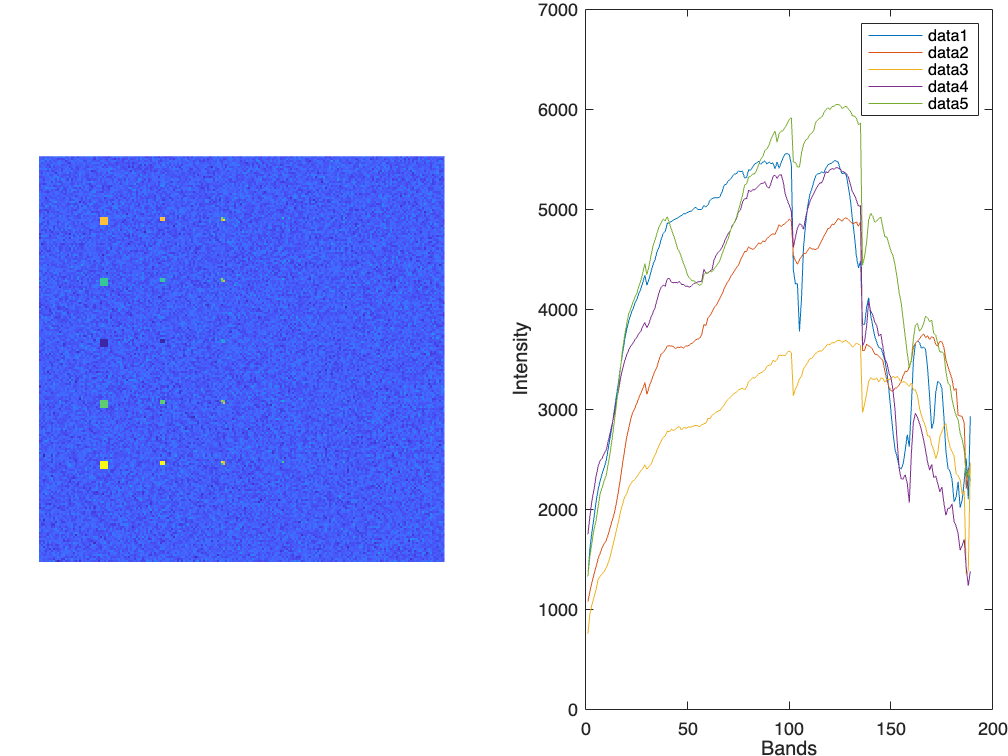

figure;
tiledlayout(1,2,"Padding","tight");

% First tile: Visualize the 100th band of the hyperspectral image
nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;

% Second tile: Plot the spectral intensity across bands
nexttile,plot(M);
legend;
xlabel("Bands");
ylabel("Intensity");

## 3. Target Detection with Desired Target Signature $\textbf{d}$

Detect targets from the TI2 hyperspectral imagery using corresponding spectra as desired target signature.

### 3.1. Constrained Energy Minimizaiton (CEM)

This block computes CEM scores for 5 target minerals and displays them as images using imagesc.  

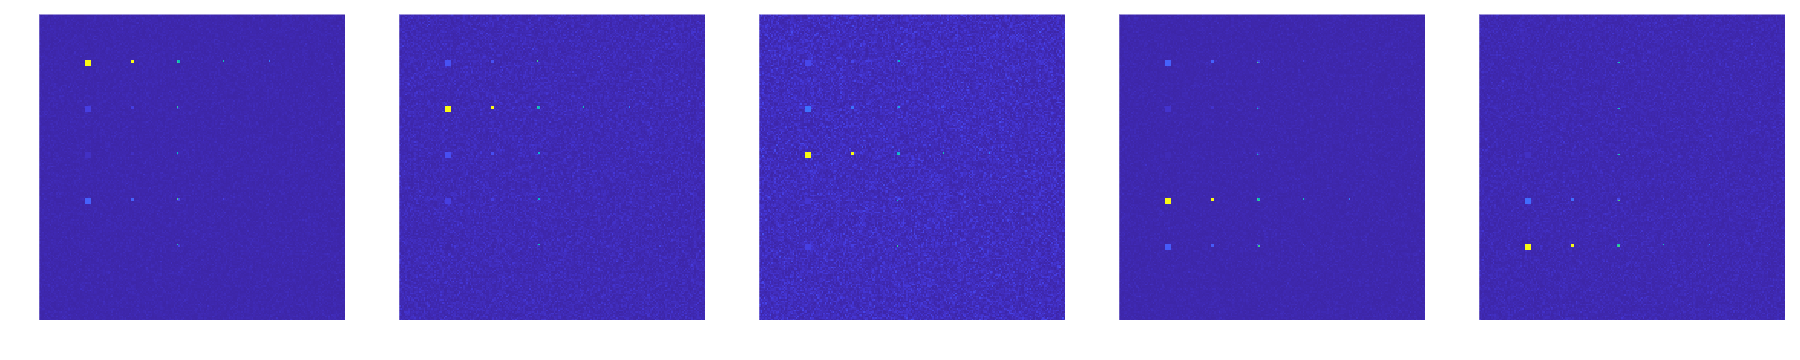

% CEM
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    scoreCEM=CEM(hsi,M(:,idx));
    nexttile,imagesc(scoreCEM),axis off,axis image;
end

### 3.2. Adaptive Cosine Estimator (ACE)

This block computes ACE scores for 5 target minerals and displays them as images using imagesc.

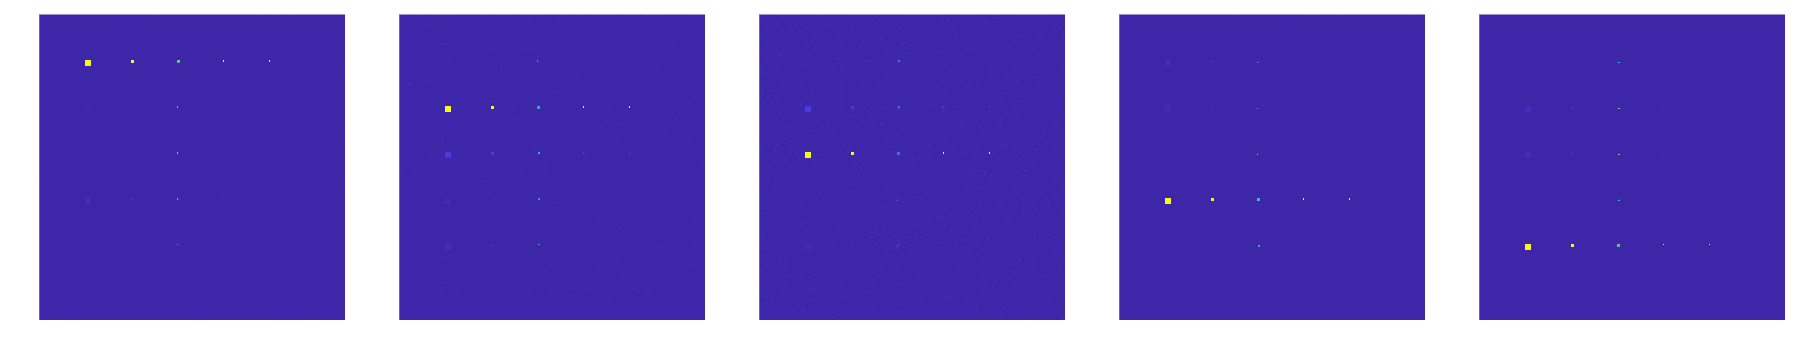

% ACE
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    scoreACE=ACE(hsi,M(:,idx));
    nexttile,imagesc(scoreACE),axis off,axis image;
end

### 3.3. Match Filter (MF)

This block computes MF scores for 5 target minerals and displays them as images using matplotlib.

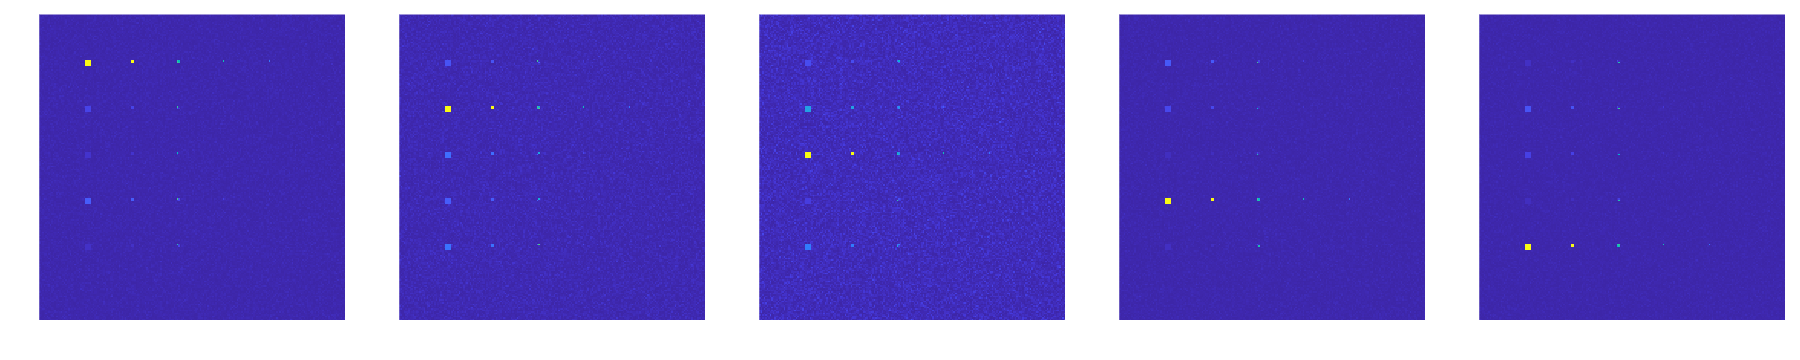

% MF
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    scoreMF=MF(hsi,M(:,idx));
    nexttile,imagesc(scoreMF),axis off,axis image;
end

## 4. Target Detection with Desired Target Signature $$\textbf{d}$$ and Undesired Target Signature $$\textbf{U}$$

Detect targets from the TI2 hyperspectral imagery using corresponding spectra as desired target signature, and the rest of the spectra as undesired target signatures.

### 4.1. Orthogonal Subspace Projection (OSP)

This block computes OSP scores for the first 5 target minerals and visualizes them.

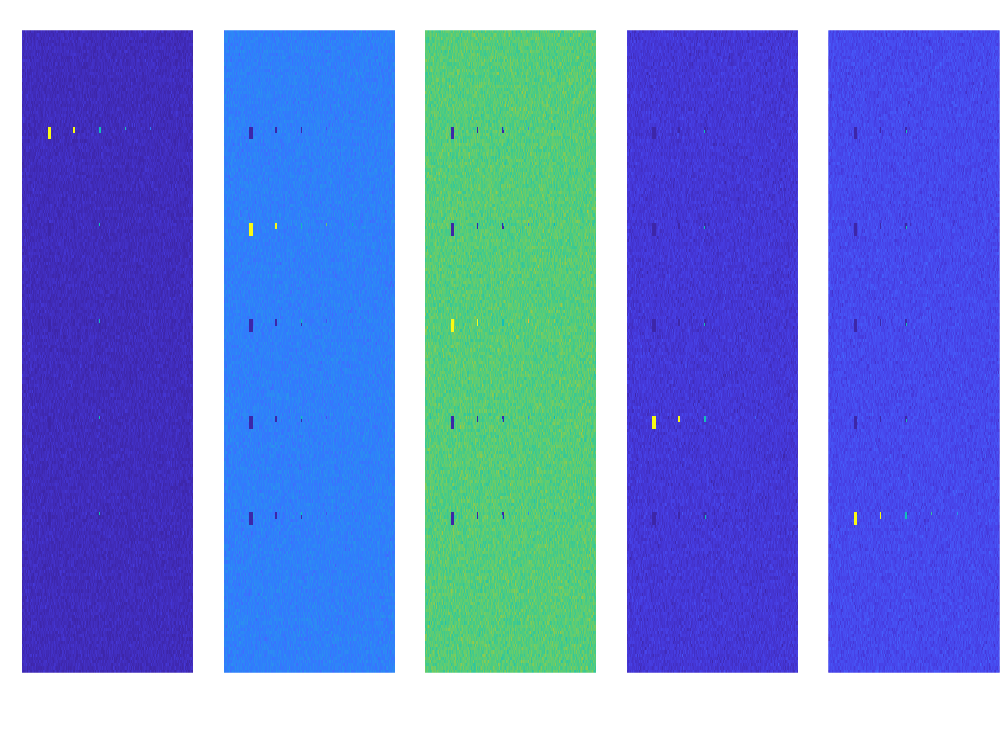

% OSP
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    d=M(:,idx);
    U=M;
    U(:,idx)=[];
    scoreOSP=OSP(hsi,d,U);
    nexttile,imagesc(scoreOSP),axis off,axis image;
end

### 4.2. Target Constrained Interference Minimizaiton Filter (TCIMF)

This block computes TCIMF scores for the second and third target minerals as desired signature and visualizes them.

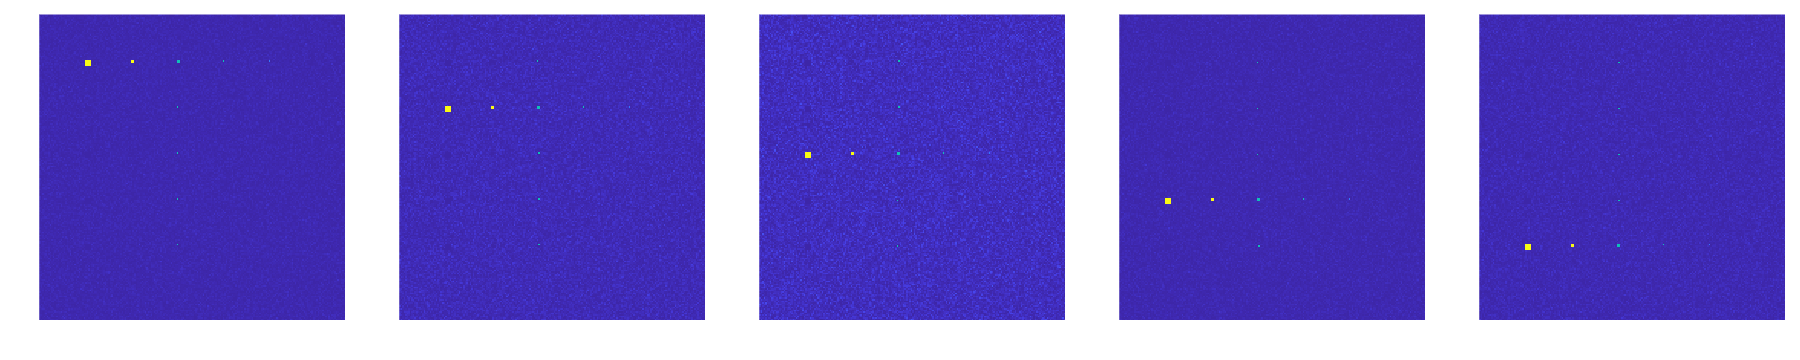

% TCIMF
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    d=M(:,idx);
    U=M;
    U(:,idx)=[];
    scoreTCIMF=TCIMF(hsi,d,U);
    nexttile,imagesc(scoreTCIMF),axis off,axis image;
end

## 5. Unsupervised Target Detection

### 5.1. Automatic Target Generation Process (ATGP)

This block visualizes the detected target positions and their spectral signatures.

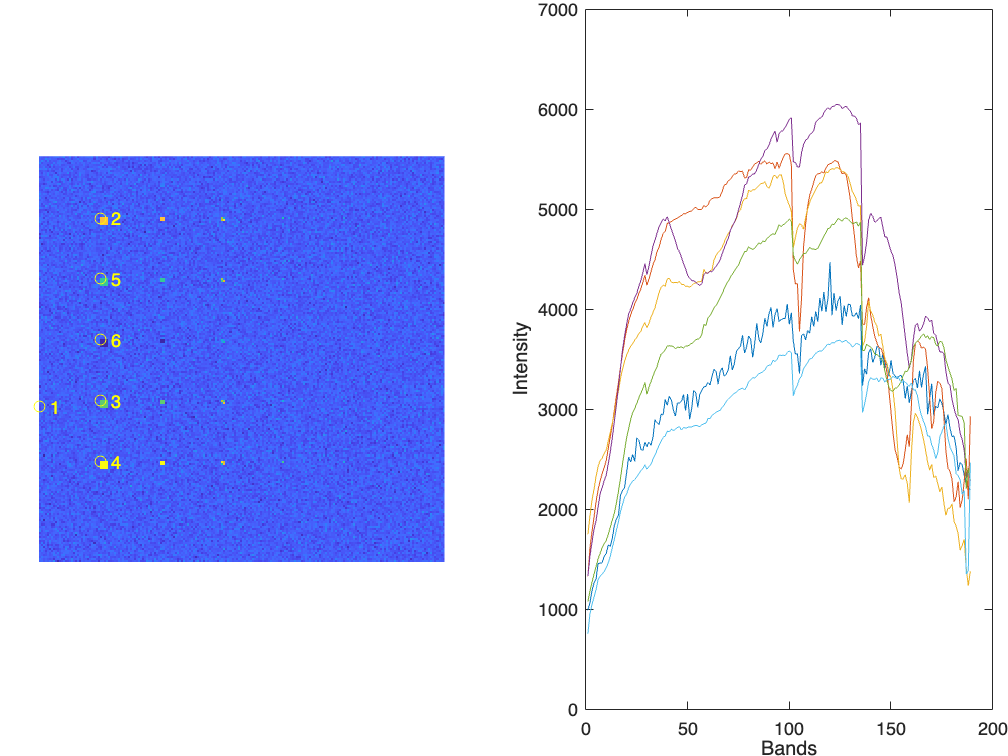

% ATGP
numTgt=6;
[posTgt,spTgt] = ATGP(hsi,numTgt);

figure;
tiledlayout(1,2,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;
for idx = 1:numTgt
    hold on,plot(posTgt(idx,2),posTgt(idx,1),'yo');
    hold on,text(posTgt(idx,2)+5,posTgt(idx,1),num2str(idx),"Color","yellow");
end

nexttile,plot(spTgt);
xlabel("Bands");
ylabel("Intensity");

## 6. Anomaly Detection

R-AD detects anomalies by computing the inverse of the auto-correlation matrix of the hyperspectral image and using it to calculate a score for each pixel. K-AD is similar to R-AD, but before calculating the score, it subtracts the mean of the hyperspectral image from each pixel, thus enhancing anomaly detection by centering the data around zero.

And this block displays the results of both the R-AD and K-AD anomaly detection methods, visualizing the anomalies detected in the hyperspectral image.

### 6.1. R-AD

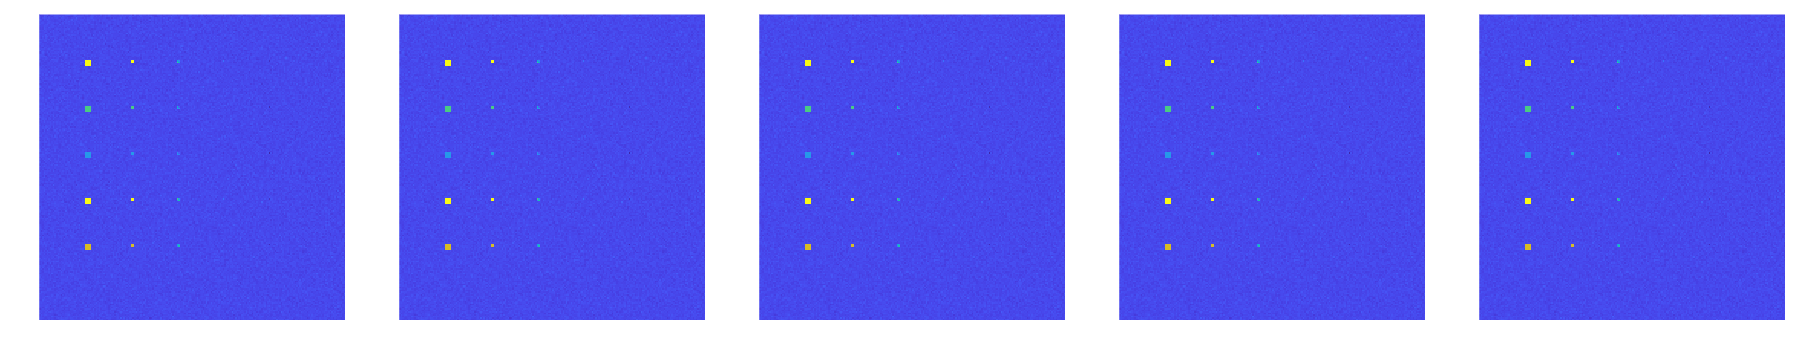

% R-AD
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    scoreRAD=RAD(hsi);
    nexttile,imagesc(scoreRAD),axis off,axis image;
end

### 6.2. K-AD

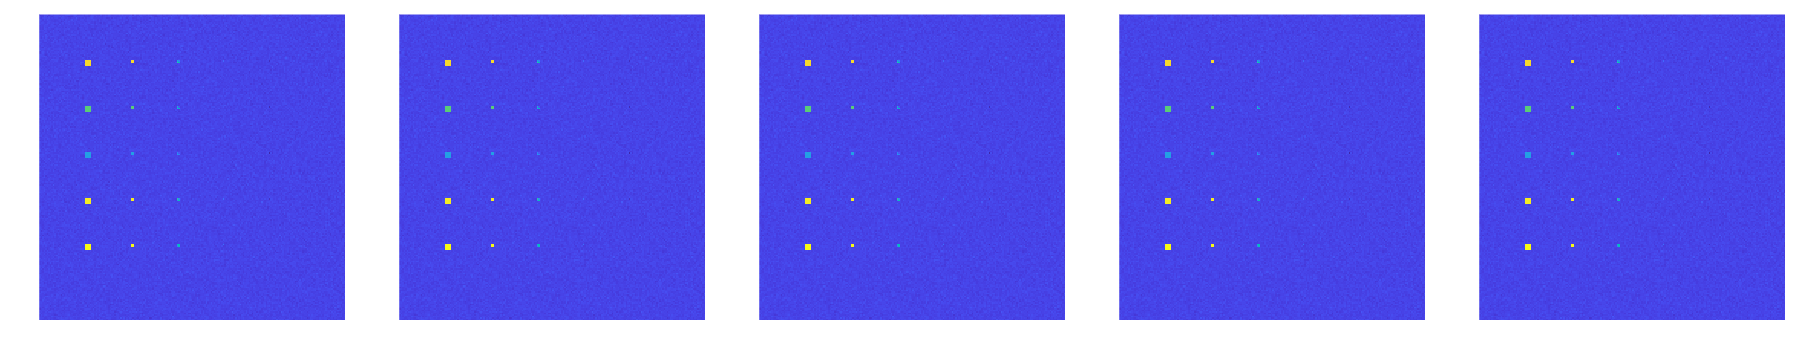

% K-AD
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    scoreKAD=KAD(hsi);
    nexttile,imagesc(scoreKAD),axis off,axis image;
end

## Functions for Above Tasks

function scoreCEM = CEM(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    R=r'*r/N;
    invR = pinv(R);

    scoreCEM = d'*invR*r'/(d'*invR*d);
    scoreCEM = abs(reshape(scoreCEM,x,y));
end

function scoreACE = ACE(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    u=mean(r,1);
    r=r-repmat(u,N,1);
    d=d-u';

    K=r'*r/N;
    invK = pinv(K);

    scoreACE = (d'*invK*r')'.^2./(d'*invK*d*sum(r*invK.*r,2));
    scoreACE=reshape(scoreACE,x,y);
end

function scoreMF = MF(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    u=mean(r,1);
    r=r-repmat(u,N,1);
    d=d-u';

    K=r'*r/N;
    invK = pinv(K);

    scoreMF = d'*invK*r'/(d'*invK*d);
    scoreMF = abs(reshape(scoreMF,x,y));
end

% OSP
function scoreOSP = OSP(HSI, d, U)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    P_U_Per=eye(L)-U*pinv(U'*U)*U';

    scoreOSP = d'*P_U_Per*r';
    scoreOSP = abs(reshape(scoreOSP,x,y));

end

% TCIMF
function scoreTCIMF = TCIMF(HSI,D,U)
    [x,y,L] = size(HSI);
    N=x*y;
    p=size(D,2);
    q=size(U,2);

    r=reshape(HSI,N,L);
    R=r'*r/N;
    invR = pinv(R);

    I=[ones(p,1);zeros(q,1)];
    w=invR*[D,U]*pinv([D,U]'*invR*[D,U])*I;

    scoreTCIMF = r*w;
    scoreTCIMF = abs(reshape(scoreTCIMF,x,y));
end

% ATGP
function [posTgt,spTgt]=ATGP(HSI,p)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);

    [~,idxTgt] = max(sum(r.^2,2));
    spTgt=r(idxTgt,:)';
    
    for idx=2:p
        U=spTgt;
        P_U_Per=eye(L)-U*pinv(U'*U)*U';
        scoreATGP = sum((r*P_U_Per).^2,2);
        [~,idxNewTgt] = max(scoreATGP);
        idxTgt(end+1)=idxNewTgt(1);
        spTgt(:,end+1)=r(idxNewTgt(1),:)';
    end

    [posTgt(:,1),posTgt(:,2)] = ind2sub([x,y],idxTgt);

end

% R-AD
function scoreRAD = RAD(HSI)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);

    R=r'*r/N;
    invR = pinv(R);

    scoreRAD = sum(r*invR.*r,2);
    scoreRAD = reshape(scoreRAD,x,y);
end

% K-AD
function scoreKAD = KAD(HSI)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    u=mean(r,1);
    r=r-repmat(u,N,1);

    K=r'*r/N;
    invK = pinv(K);

    scoreKAD = sum(r*invK.*r,2);
    scoreKAD = reshape(scoreKAD,x,y);
end